## BCI Competition 2008 – Graz data set A

This data set consists of EEG data from 9 subjects. The cue-based BCI paradigm consisted of four different motor imagery tasks, namely the imagination of movement of the left hand (class 1), right hand (class 2), both feet (class 3), and tongue (class 4). Two sessions on different days were recorded for each subject. Each session is comprised of 6 runs separated by short breaks. One run consists of 48 trials (12 for each of the four possible classes), yielding a total of 288 trials per session.

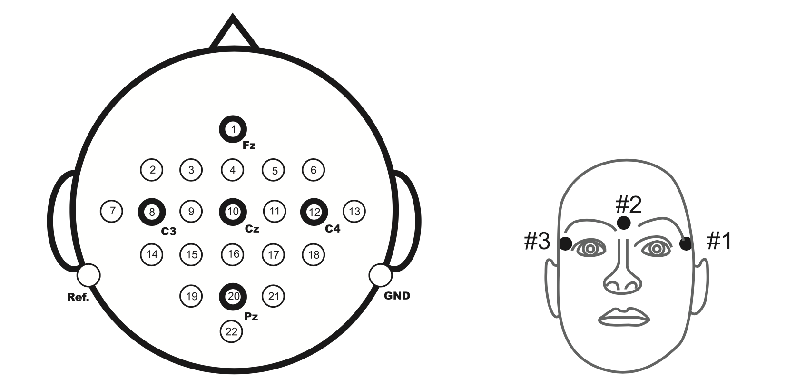

## Load Data

Twenty-two Ag/AgCl electrodes (with inter-electrode distances of 3.5 cm) were used to record the EEG; the montage is shown in Figure 3 left. All signals were recorded monopolarly with the left mastoid serving as reference and the right mastoid as ground. The signals were sampled with 250 Hz and bandpass-filtered between 0.5 Hz and 100 Hz. The sensitivity of the amplifier was set to 100 µV. An additional 50 Hz notch filter was enabled to suppress line noise.

mat = dir('./data/*.mat');
for K = 1 : length(mat)
  thisfile = mat(K).name;
  thisdata = load(strcat('./data/',thisfile));
end

## Plot a subject trial signals 

data = thisdata.data;
data{1,6}

ans =             X: [96735x25 double]
        trial: [48x1 double]
            y: [48x1 double]
           fs: 250
      classes: {'left hand'  'right hand'  'feet'  'tongue'}
    artifacts: [48x1 logical]
       gender: 'male'
          age: 17


So we have for each subject a train and evaluation dataset. We will start by analyzing the evaluation dataset that contains 8 attributes. The X attributes contains the 25 channels signals values (22 EEG and 3 EOG) samplified with a rate of 250 Hz and bandpass-filtered between 0.5 Hz and 100 Hz. The trial vector contains run index and the y vector contains the target value with subject informations.

data{1,6}.X

ans =    -2.9785  -10.2539   -1.8555    5.4688    9.4238   13.5742  -21.4844  -22.9004   -8.5938    7.5684   14.2090   22.0703   18.4082  -40.0391  -19.8730   -4.0039    7.5195   14.1602  -26.5625  -10.6445   -3.8086  -17.9688   -2.4414  -22.4609   11.2305
   -0.2930   -4.9805    3.2715    8.2031    9.4727    9.2773  -13.2324  -17.6270   -4.4922    7.4219   11.3281   14.3555    9.1797  -37.4023  -19.2871   -8.1543    1.5137    5.9082  -27.2949  -14.8926   -8.3984  -16.6992    7.3242  -23.9258    7.8125
   -2.2949    2.2949    4.1992    9.2773    6.4453    6.5430    2.2949   -6.9336   -2.7344    6.9336    5.3711    9.1309    7.8125  -28.2715  -18.9941   -9.3262   -5.6641   -3.7598  -29.3945  -19.8730  -14.8438  -18.5547    4.3945  -25.3906    8.7891
  -13.4766  -17.4805  -11.9141   -8.9844   -7.8613  -10.9863  -31.2012  -27.0020  -18.7500  -12.8906  -12.8906  -15.2344   -9.5215  -42.7246  -33.6914  -28.6133  -24.8535  -23.9258  -42.7734  -35.0098  -30.6152  -28.6133   -2.4414  -35.1562 

data{1,6}.trial

ans =          251
        2254
        4172
        6124
        8132
       10243
       12160
       14210
       16141
       18139


eeg_signal=data{1,6}

eeg_signal =             X: [96735x25 double]
        trial: [48x1 double]
            y: [48x1 double]
           fs: 250
      classes: {'left hand'  'right hand'  'feet'  'tongue'}
    artifacts: [48x1 logical]
       gender: 'male'
          age: 17


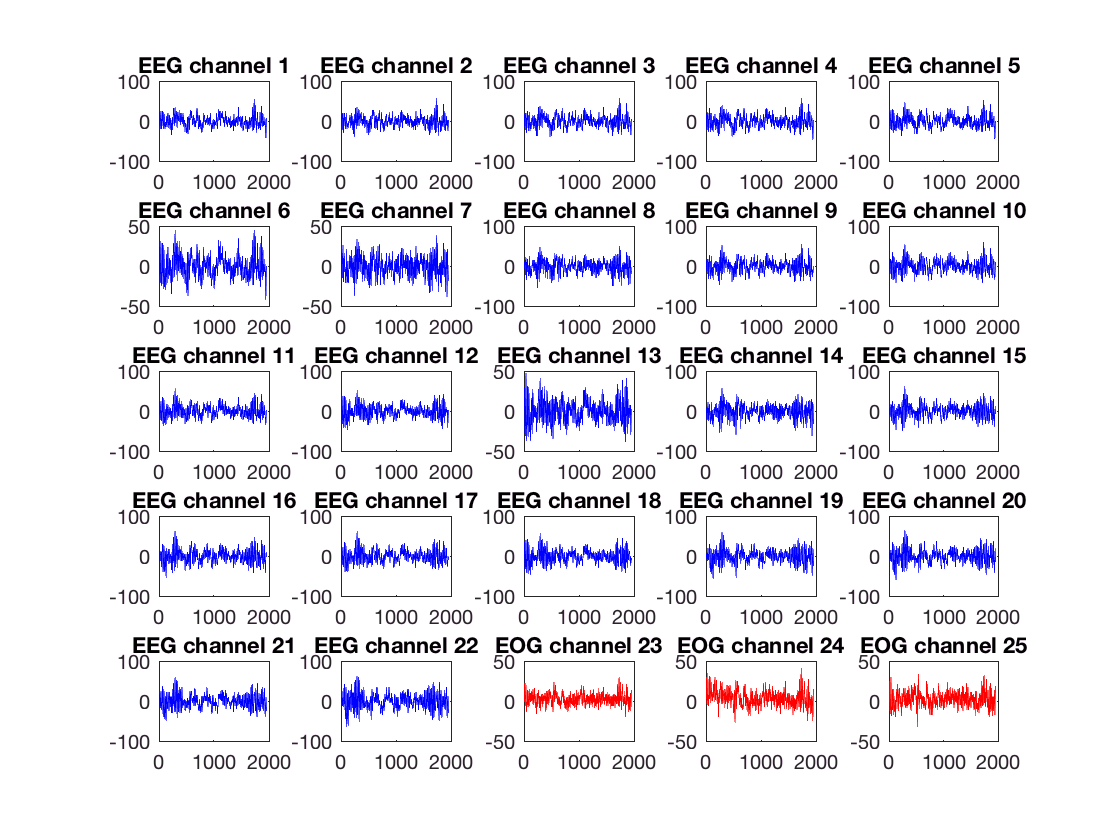

figure
for k=1:25
    signal_type='EEG';
    color='blue';
    if k>22
        signal_type = 'EOG';
        color='red';
    end
    subplot(5,5,k);
    plot([1:48165-46212],data{1,7}.X(46212:48164,k:k),color);
    %xlim([1 48165-46212]);
    title(sprintf('%s channel %s',signal_type,int2str(k)));
end

We plot differents channels signals for a signal trial for a specific subject. We used the function plot_signal( data, subject,trial_start, trial_end ) to do that. 

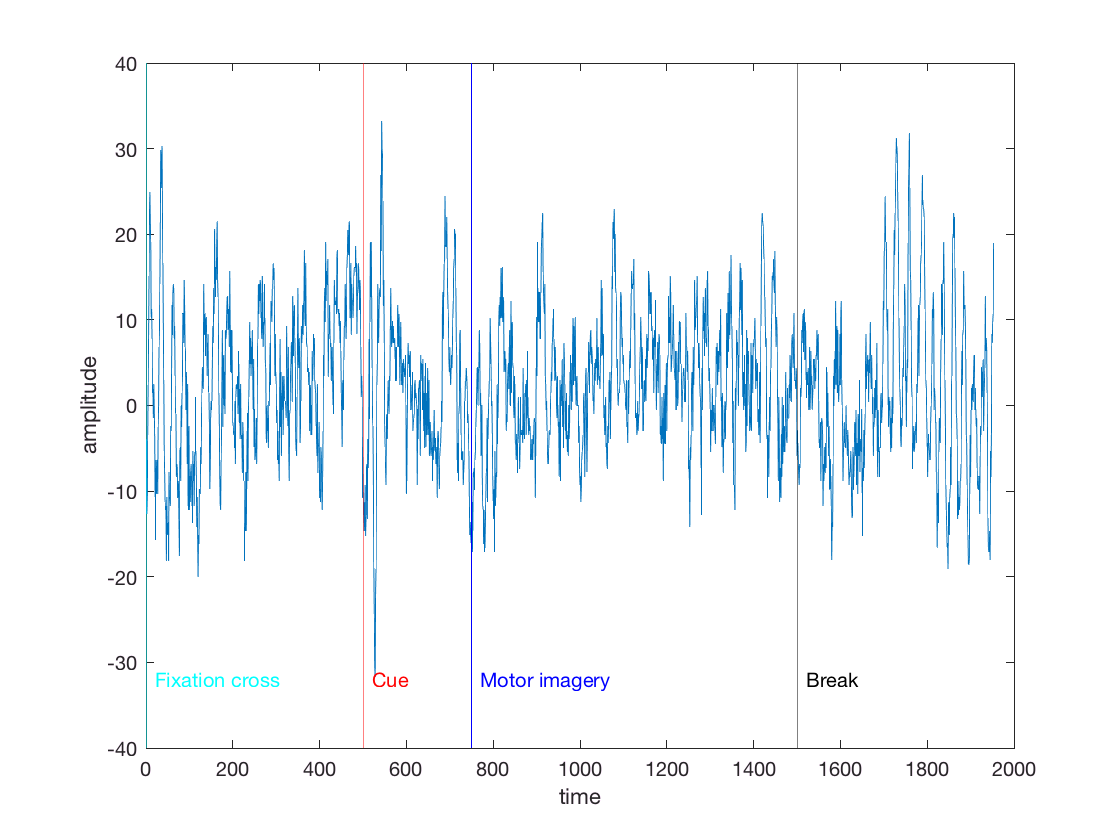

figure
for i=25:25
    plot([1:48165-46212],data{1,7}.X(46212:48164,i));
    vline(0,'c','Fixation cross');
    vline(500,'r','Cue');
    vline(750,'b','Motor imagery');
    vline(1500,'k','Break');
    ylabel('amplitude')
    xlabel('time')
    hold on;
end

The subjects were sitting in a comfortable armchair in front of a com- puter screen. At the beginning of a trial (t = 0 s), a fixation cross appeared on the black screen. In addition, a short acoustic warning tone was pre- sented. After two seconds (t = 2 s), a cue in the form of an arrow pointing either to the left, right, down or up (corresponding to one of the four classes : left hand, right hand, foot or tongue) appeared and stayed on the screen for 1.25s. This prompted the subjects to perform the desired motor imagery task. No feedback was provided. The subjects were ask to carry out the motor imagery task until the fixation cross disappeared from the screen at t = 6s. A short break followed where the screen was black again. 

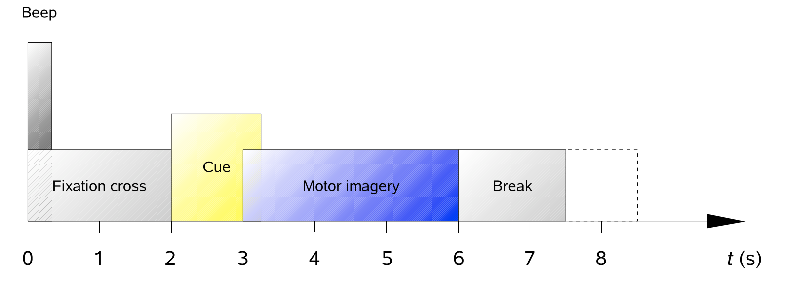

## Generate features : 

***Generate Common Spatial Pattern (CSP)***

Motor imagery is a mental process of a motor action. It includes preparation for movement, passive observations of action and mental operations of motor representations implicitly to explicitly. The ability of an individual to control his EEG through imaginary mental tasks enables him to control device through brain computer interface (BCI). 

EEG signals are formalized as : $\Big\{ E_n \Big\}_{n=1}^N  \in R^{channel \times time}$, $N = 9 \times 48 = 432$is the number of trials, $channel = 22 $ EEG channels, $time = 250 \times 3 = 750$ is the range of time domain. We used 2.5 s for fixation cross and 1.5 s for cue and 3s with a rate of 250 Hz for motor imagery.

We have to transform each EEG signal to feature vector $E_n \in R^{channel \times time} \longrightarrow x_n \in R^{d}$ where $d$is the number of features for each channel, so we will have $d \times channel$ feature for each subject.

The CSP filters is an effective method of feature extraction for EEG motor imagery classification, it's the most popular algorithm in BCI field for learning spatial filters for oscillatory processes. 

***Signal power ***

Here, we will generate same handcrafted features associated to the signal, We will start by generate the power of the discrete signal. The power of a discrete signal is defined as $E_x = \sum \limits_{-\infty} ^{+\infty}{\mid x(n) \mid }^2$, we calculate the average signal power for each channel and each MI action. In this case we consider all the signal informations (~ 8 s) and not only the Motor Imagery part of the signal. 

subjects = [4:9]; % We have only 6 subject train data 
[line,nb_subject] = size(subjects);
[nb_trials,column] = size(data{1,5}.trial);
targets = []; %target of trial, contaisn the target class
[nb_observations,nb_channels] = size(data{1,5}.X);
%features_vectors = zeros(nb_trials*nb_subject,3*nb_channels); %initialize the features vector
features_vectors = [];
trials = [1:48:288];

for s=1:nb_subject
    for k=2:nb_trials
        start_index = data{1,subjects(s)}.trial(k-1);
        end_index = data{1,subjects(s)}.trial(k);
        mean_array = data{1,subjects(s)}.X(start_index:end_index,:);
        power_array = abs(data{1,subjects(s)}.X(start_index:end_index,:)).^2; % calculate power of the discrete signal ( we take all the signal ) 
        power_array_motor_imagery = power_array(750:1500,:); % calculate power of the discrete signal ( we take only the motor imagery part )
        signals_features = [sum(power_array) sum(power_array_motor_imagery) mean(mean_array)];
        %features_vectors(k,:)=signals_features
        features_vectors = [features_vectors;signals_features];
    end
    targets = [targets;data{1,subjects(s)}.y];
end
targets(trials,:)=[];

We construct 3 sample handcarfted features, the signal mean, the power of all the signal and the power of the motor imagery part of the signal for each EEG and MOG channel. So we have a $ R^{3 \times 25} $ features vector.

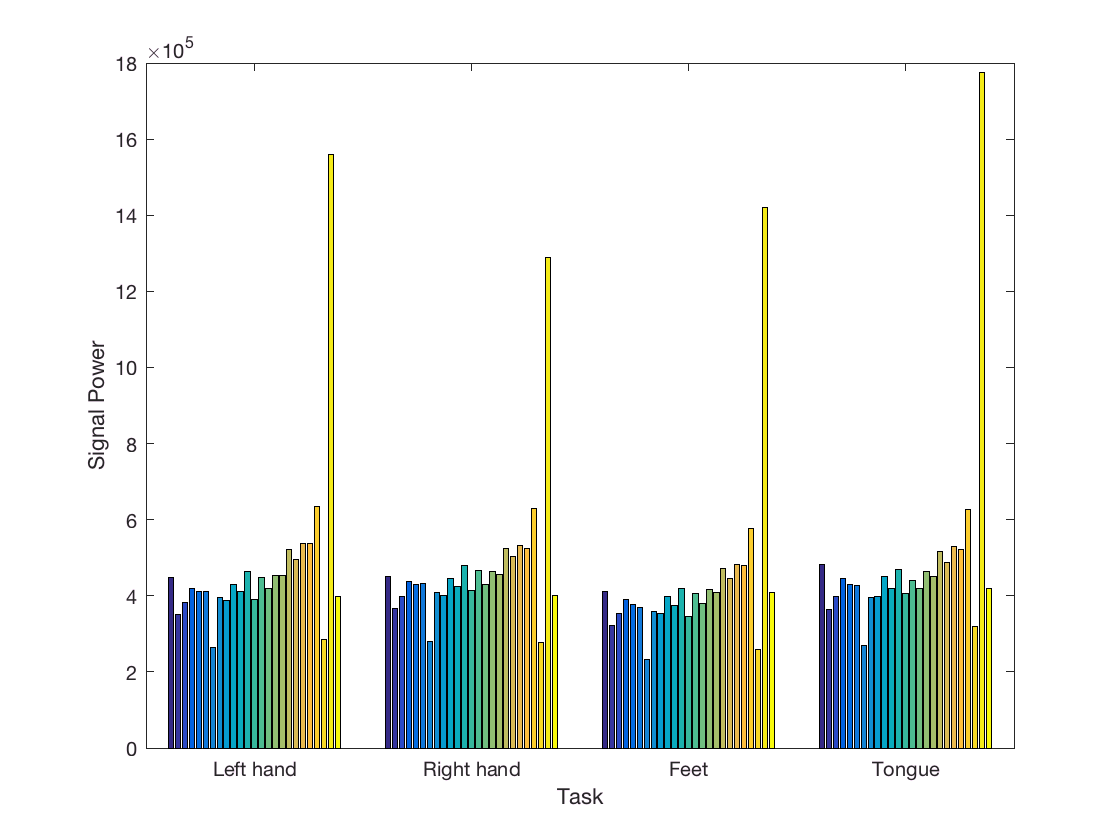

figure
power_array = [];
for k=1:4
    ind = targets == k;
    A1 = features_vectors(ind,1:25);
    power_array = [power_array;mean(A1)];
end
bar(power_array);
set(gca,'xticklabel',{'Left hand','Right hand','Feet','Tongue'});
ylabel('Signal Power');
xlabel('Task');

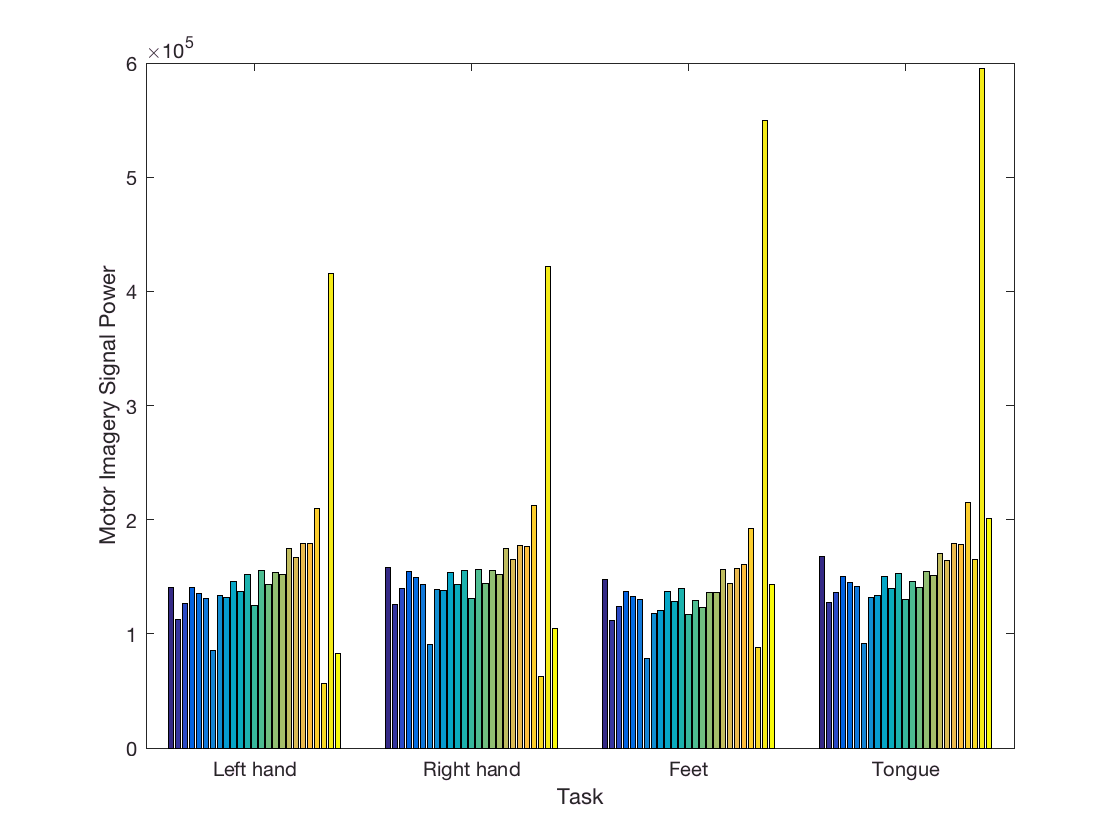

figure
power_array = [];
for k=1:4
    ind = targets == k;
    A2 = features_vectors(ind,26:50);
    power_array = [power_array;mean(A2)];
end
bar(power_array);
set(gca,'xticklabel',{'Left hand','Right hand','Feet','Tongue'});
ylabel('Motor Imagery Signal Power');
xlabel('Task');    

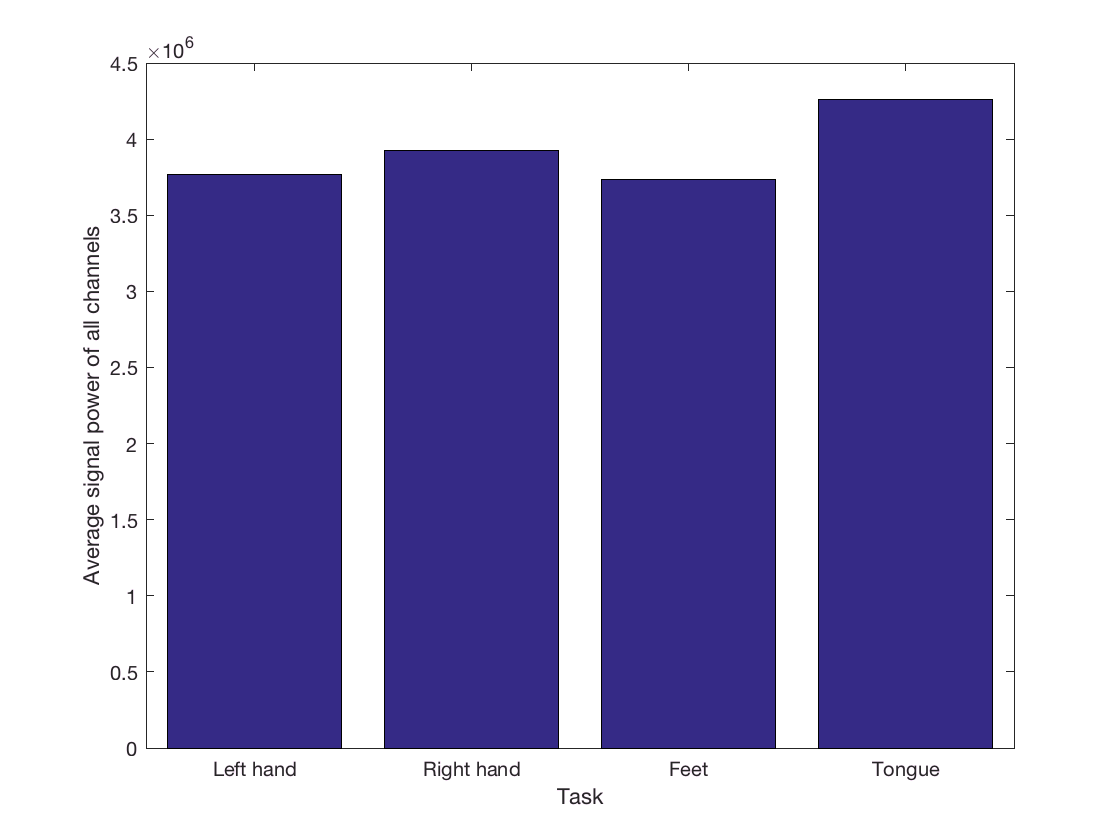

figure;
bar(sum(power_array,2));
set(gca,'xticklabel',{'Left hand','Right hand','Feet','Tongue'});
ylabel('Average signal power of all channels');
xlabel('Task');

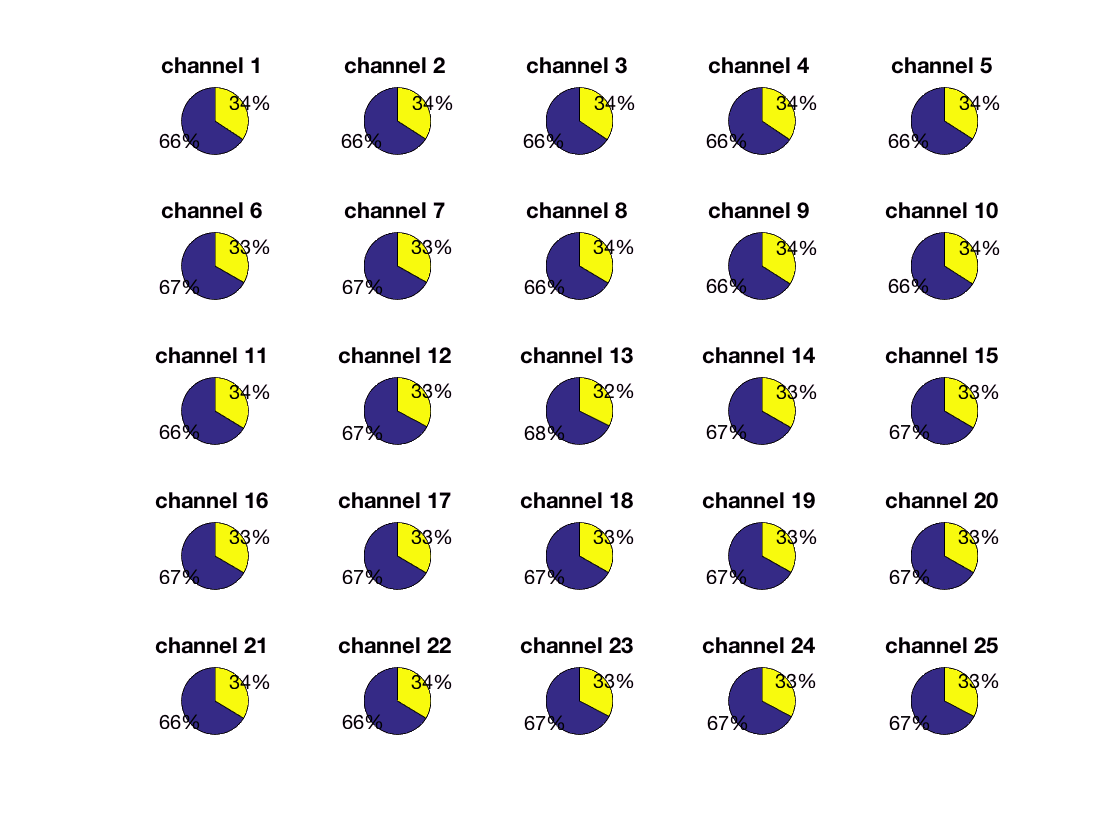

motor_imagery_power = sum(features_vectors(:,26:50));
signal_power = sum(features_vectors(:,1:25));
power_percent_array = motor_imagery_power./signal_power * 100;
figure;
for c=1:25
    subplot(5,5,c);
    A = [100-power_percent_array(1,c)];
    A = [A;power_percent_array(1,c)];
    pie(A);
    title(sprintf('channel %s ',int2str(c)));
end

## Discrete Fourier transform (DFT)

The discrete Fourier Transform trasnforms a sequence of N complex numbers $x_0,x_1, ... , x_{N-1}$ in other sequence of complex numbers $X_0,X_1, ... , X_{N-1}$ which is defined by $X_k = \sum \limits_{n=0} ^{N+1} {x_n . e^{-2 \pi kn/N}$, so lets do some study in the frequency domain (spectral). The DFT transform the signal from the time domain into the frequency domain, requires that the signal be stationary. We will focus randomly on a channel and a subject, lets say C3 (channel 3)

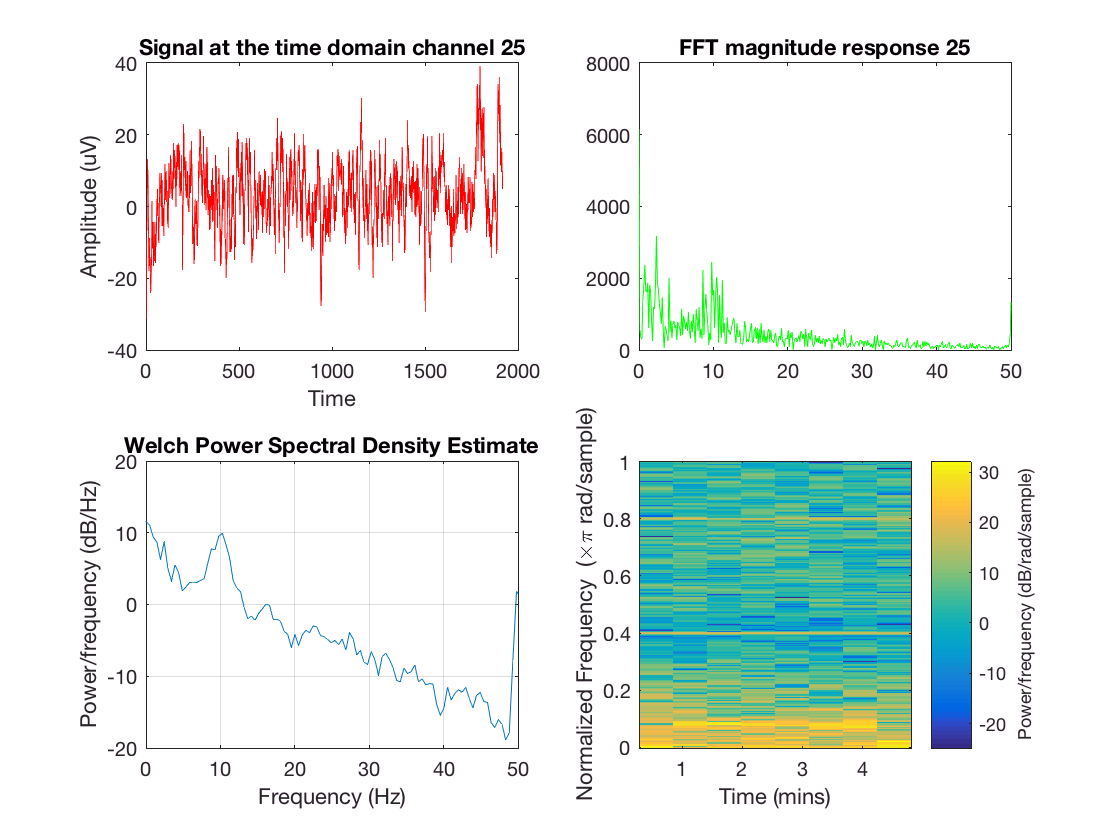

Fs = 250;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = 4172-2254;
channel = 25;
time_eeg = data{1,6}.X(2254:4172,channel:channel);
figure 
subplot(2,2,1)
plot([1:4172-2253],time_eeg,'red')
title(sprintf('Signal at the time domain channel %d',channel))
xlabel('Time')
ylabel('Amplitude (uV)')



frequency_eeg = fft(time_eeg);
X_mag = abs(frequency_eeg); %retrieve magnitude informations 
X_phase = angle(frequency_eeg); %retrieve phase informations
N = length(frequency_eeg);
Fbins = ((0:1/N:1-1/N)*Fs);
subplot(2,2,2)
plot(Fbins, X_mag,'green');
title(sprintf('FFT magnitude response %d',channel));
xlim([0 50])


subplot(2,2,3);
pwelch(time_eeg,[],[],[],Fs);
xlim([0 50]);

s = spectrogram(time_eeg);
subplot(2,2,4);
spectrogram(time_eeg,'yaxis');

## SVM Classifier (v 1.0)

[nrow,ncol] = size(features_vectors);
[trainInd,testInd] = dividerand(nrow,0.8,0.2);
train_data = features_vectors(trainInd,:);
target = targets(trainInd,:);
test_data = features_vectors(testInd,:);
Mdl = fitcecoc(train_data,target);
label = predict(Mdl,test_data);
sum(targets(testInd,:)==label)/49

ans = 0.2245